# Examples 5.3-5.6: Heat Capacity Parameters

Note: this script reproduces Examples 5.3 to 5.6 (Section 5.2) of **Statistics for Chemical Engineers**: estimating a quadratic model of heat capacity versus temperature from calorimetry data. Victor Z UW-Madison, 2020 linear regression for heat capacity see [https://www.mathworks.com/help/stats/understanding-linear-regression-outputs.html](https://www.mathworks.com/help/stats/understanding-linear-regression-outputs.html)

clc; clear all; close all hidden;

## Data

generate data (true model is Cp=a0+a1*T+a2*T^2) CP in cal/mol-K and T in K

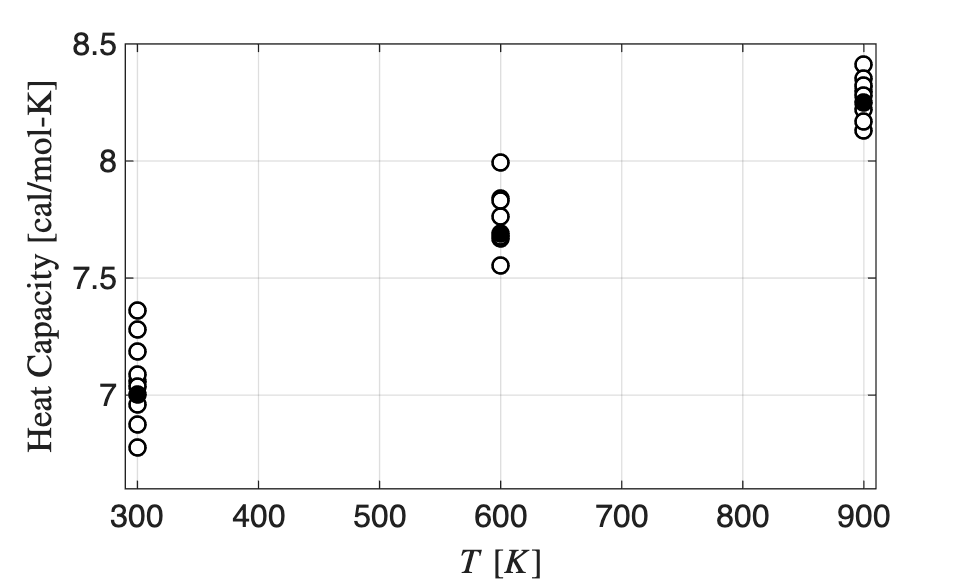

a0=+0.6190e+1;
a1=+0.2923e-2;
a2=-0.7052e-6;
theta=[a0,a1,a2]';

% 3 sets of experiments at T=300K, T=400K, and T=500K
n=10;
N=3*n;
x1=linspace(300,300,n)';
x2=linspace(600,600,n)';
x3=linspace(900,900,n)';
 x=[x1; x2; x3];
    
% generate true outputs 
rng(0);
y1=a0+a1*x1+a2*x1.^2;
y2=a0+a1*x2+a2*x2.^2;
y3=a0+a1*x3+a2*x3.^2;
ytrue=[y1; y2; y3];

% add random noise to true outputs
sigma=0.1;
y=ytrue+normrnd(0,sigma,N,1);

%%%%% Visualize data

 figure(1)
 scatter(x,y,'blacko','MarkerFaceColor','w','LineWidth',1)
 hold on
 scatter(x,ytrue,'blacko','MarkerFaceColor','black','LineWidth',1)
 xlabel('$T\; [K]$','Interpreter','latex','FontSize',16)
 ylabel('$\textrm{Heat Capacity [cal/mol-K]}$','Interpreter','latex','FontSize',16)
 grid on
 box on
 set(gca,'FontSize',12)
 axis([290 910 6.6 8.5])
 print -depsc ch5_heat_capacity_data.eps

## Estimates, covariance, and Fisher information (Examples 5.3-5.5)

construct input and output data matrix for MLE

xsq=x.^2;
X=[ones(N,1),x,xsq];
Y=y;

% assume noise variance is not known and obtain best fit parameters
% by solving SSE minimization problem
thetaest=inv(X'*X)*X'*Y

thetaest =    6.1985e+00
   3.1794e-03
  -9.6020e-07



% confirm that this minimizer is unique
format long e
eigs(X'*X)

ans =      7.938011902061862e+12
     6.979676108535849e+05
     5.263086456623183e-01



% get model predictions
Yhat=X*thetaest;

% get residuals
e=Y-Yhat;

% visualize fit
figure(2)
subplot(2,2,1)
xx=linspace(6.5,8.5);
plot(Y,Yhat,'blacko','MarkerFaceColor','w')
hold on
plot(ytrue,Yhat,'blacko','MarkerFaceColor','black')
plot(xx,xx,'black')
grid on
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}$','Interpreter','latex','FontSize',14)
axis([6.5 8.5 6.5 8.5])

pd = fitdist(e,'Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 2.66927e-13   [-0.0481496, 0.0481496]
    sigma =    0.128947   [0.102694, 0.173345]


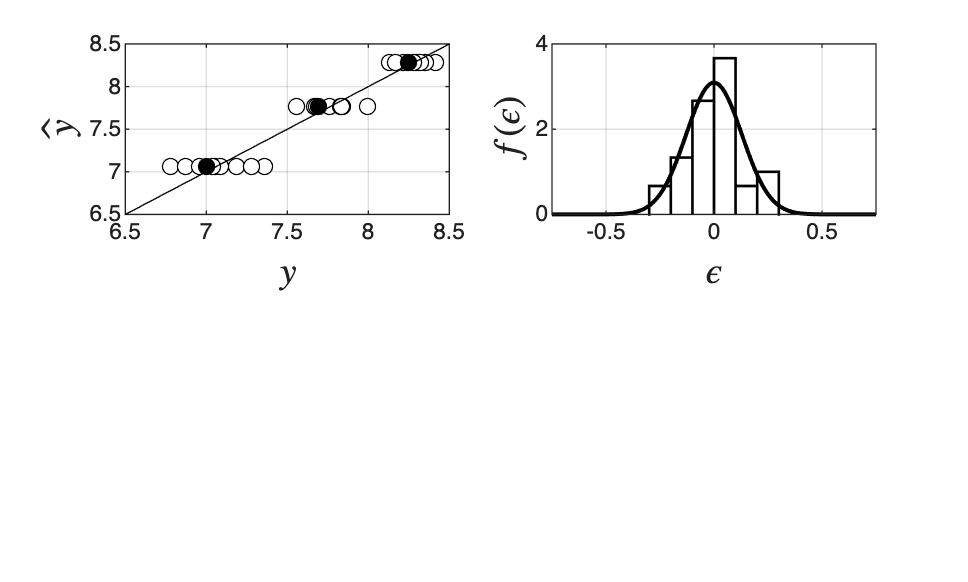

subplot(2,2,2)
histogram(e,'BinWidth',0.1,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
xx=linspace(-0.75,0.75);
plot(xx,normpdf(xx,pd.mu,pd.sigma),'black-','LineWidth',1.5)
axis([-0.75 0.75 0 4])
grid on
xlabel('$\epsilon$','Interpreter','latex','FontSize',14)
ylabel('$f(\epsilon)$','Interpreter','latex','FontSize',14)
print -depsc ch5_heat_capacity_fit.eps


% assume variance of error is from output measurement
sig2=var(e)

sig2 =      1.662733268854964e-02

sigest=sqrt(sig2)

sigest =      1.289470150431938e-01


% get covariance matrix for parameters
 C=inv(X'*X)*sig2

C =      3.159193210824485e-02    -1.163913288198496e-04     9.237407049194421e-08
    -1.163913288198496e-04     4.526329454105265e-07    -3.694962819677768e-10
     9.237407049194421e-08    -3.694962819677768e-10     3.079135683064806e-13


 
% determine Fisher information matrix
 I=inv(C)

I =      1.804258118962166e+03     1.082554871377305e+06     7.577884099641165e+08
     1.082554871377305e+06     7.577884099641145e+08     5.845796305437461e+11
     7.577884099641165e+08     5.845796305437461e+11     4.774066982773922e+14


 
% get R2
Ybar=mean(Y)

Ybar =      7.702805562202472e+00

Sm=norm(Yhat-Ybar)^2

Sm =      7.446457727248633e+00

Se=norm(Y-Yhat)^2

Se =      4.821926479679396e-01

Sy=norm(Y-Ybar)^2

Sy =      7.928650375220857e+00


R2=Sm/Sy

R2 =      9.391835148288031e-01

R2=1-Se/Sy

R2 =      9.391835148293435e-01

## get Pearson correlation and confirm this is related to R2

rho=sqrt(R2)

rho =      9.691148099319005e-01

rho=corr(Y,Yhat)

rho =      9.691148099319005e-01


% get qqplot of residuals
figure(3)
h=qqplot(e)

h =   3×1 Line array:

  Line    (Data)
  Line    (Reference Mid)
  Line    (Reference Ends)

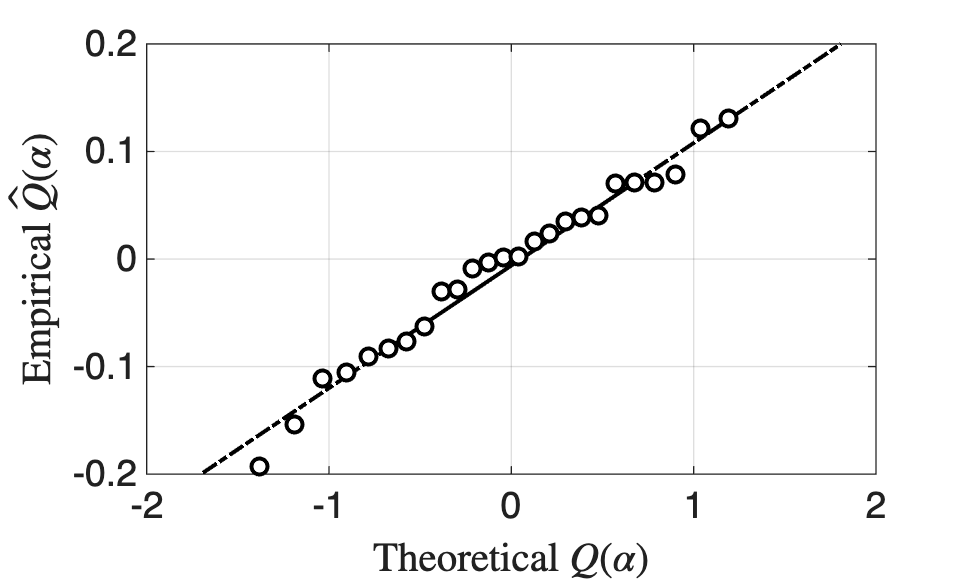

xlabel('Theoretical $Q(\alpha)$','Interpreter','latex','FontSize',14)
ylabel('Empirical $\hat{Q}(\alpha)$','Interpreter','latex','FontSize',14)
title('')
set(gca,'FontSize',14)
set(h,'Color','black','LineWidth',1.5,'Marker','o','MarkerFaceColor','white','MarkerEdgeColor','black')
grid on
axis([-2 2 -0.2 0.2])
box on
print -depsc ch5_qqplot_heatcapacity.eps

## try matlab built-in functions and compare wit our calculations

X = [x xsq];
Y = y;
lm = fitlm(X,Y,'linear')

lm = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                         Estimate                    SE                     tStat                   pValue       
                   _____________________    ____________________    _____________________    ____________________
    (Intercept)     6.19846741057518e+00    1.84206610162022e-01     3.36495384455705e+01    1.39254411704646e-23
    x1              3.17936869707999e-03    6.97252688583817e-04     4.55985147011420e+00    9.93815056797271e-05
    x2             -9.60197777668347e-07    5.75084324924367e-07    -1.66966431887120e+00    1.06541229948751e-01

Number of observations: 30, Error degrees of freedom: 27
Root Mean Squared Error: 0.134
R-squared: 0.939,  Adjusted R-Squared: 0.935
F-statistic vs. constant model: 20

## Note

As in the book, the model captures the trend, the residuals are Gaussian (purely random), and the parameter variances are small: the Fisher information shows a sharp minimum and precise estimates.